# **CS/SE 4X03 Tutorial Week 7 - Regression**

## Idea Behind Regression:

Regression will contrast to interpolation.

With interpolation we had that each data point is exactly represented by our interpolation function.

With regression, we do not have this requirement. 

Consider if the data has uncertainty, we would not expect the underlying function to exactly fit our data, instead we would expect to see a general trend with a spread of data.

clf;
clear;
n = 5;
% Data we have
xi = 1:n;
yi = [3.4 3.7 4.9 5.4 5.3];

% Our regression, this will be explained later in tutorial
A = [xi*xi' sum(xi); sum(xi) n];
b = [yi*xi'; sum(yi)];
coeffs = A\b

coeffs =     0.5500
    2.8900


So we obtain a regressed line that is equal to: $y = 0.55x + 2.89$. 

% The actual func
y = 0.5*xi+3;

plot(xi,y,'--');
hold on;
xlim([0.5 5.5])
plot(xi,coeffs(1)*xi+coeffs(2));
plot(xi,yi,'o')

leg = legend('Actual','Fit','Points','Location','northwest');

When plotted against the actual $y=0.5x+3$, we see no data points exactly match, unlike with interpolation.

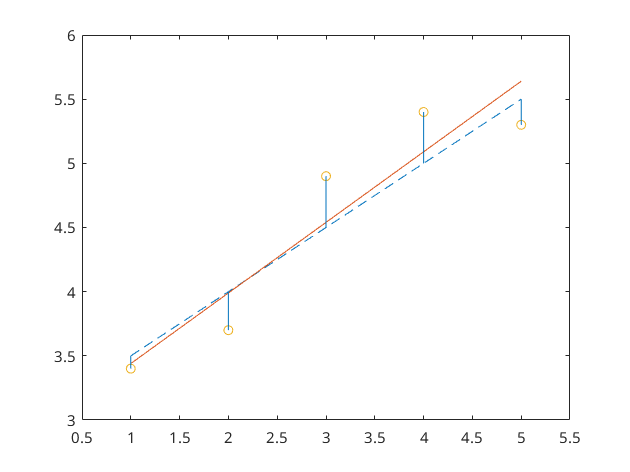

for i = xi
 line([xi(i) xi(i)], [y(i) yi(i)]);
end
set(leg,'visible','off');

## Exercise 1 - 9.1.3

**Q: **Find an equation of the form $y=ae^{x^2}+bx^3$ that best fits the points $(-1,\,0),\,(0,\,1)$and $(1,\,2)$in the least squares sense.

**A: **Let:


$$\varphi=\sum_{k=0}^m\left(ae^{x_k^2}+bx_k^3-y_k\right)^2$$


Given that we have three data points, we know $m=2$.

Now we write out this summation explicitly for our points:


$$\varphi=(ae^{(1^2)}-b(1)^3-(0))^2+(ae^{0^2}-b(0)^3-(1))^2+(ae^{(1)^2}+b(1)^3-(2))^2$$


Now we want to solve for $\partial_a\varphi=0$ and $\partial_b\varphi=0$:


$$\partial_a\varphi=2e(ae-b)+2(a-1)+2e(ae+b-2)=0$$



$$\Rightarrow a=\frac{2e+1}{2e^2+1}$$



$$\partial_b\varphi=-2(ae-b)+2(ae+b-2)=0$$



$$\Rightarrow b=1$$


Now we substitute $a$ and $b$ into $y$:


$$y=e^{x^2}\left(\frac{2e+1}{2e^2+1}\right)+x^3$$


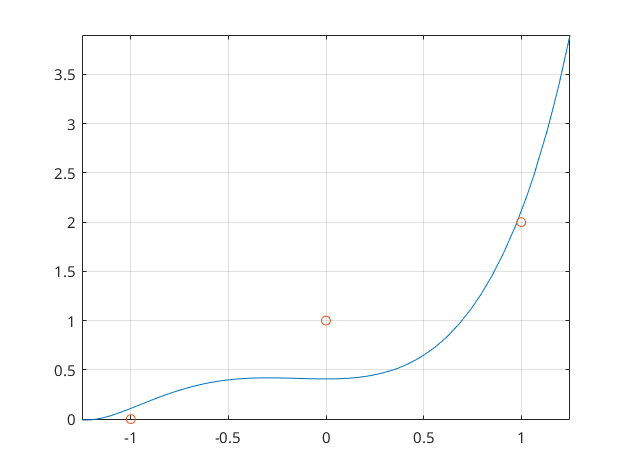

clf;
clear;
syms x;
e = exp(1);
y(x)=e^(x^2)*(2*e+1)/((2*e^2+1))+x^3;
fplot(y)
xlim([-1.25 1.25]);
hold on;
coeffs = [-1;0;1];
D = [0;1;2];
plot(coeffs,D,"o");
grid on;

## **Exercise 2 - 9.1.5**

**Q: **Find the equation of a parabola of the form: $y=ax^2+b$ that best represents the following data. Use the method of least squares.


$$\begin{array}{ll}
x \;\\ \hline
y\;
\end{array}
\left|
\begin{array}{ccc}
\;-1 & 0 & -1\\\hline
\;3.1 & 0.9 & 2.9
\end{array}$$


**A:** Let:


$$\varphi = \sum_{k=0}^m(ax^2+b-y_k)^2$$


Given that we have three data points, we know $m=2$.

Now we write out this summation explicitly for our points:


$$\varphi=(a+b-3.1)^2+(b-0.9)^2+(a+b-2.9)^2$$


Now we want to solve for $\partial_a\varphi=0$ and $\partial_b\varphi=0$:


$$\partial_a\varphi=2(a+b-3.1)+2(a+b-2.9)=0$$



$$\Rightarrow 4a+4b = 12$$



$$a+b=3$$



$$\partial_b\varphi=2(a+b-3.1)+2(b-0.9)+2(a+b-2.9)=0$$



$$\Rightarrow 4a+6b=13.8$$


This is really just a linear problem:


$$\textbf{A}x=b$$



$$\left[\matrix{1 & 1\cr 4 &6}\right]\left[\matrix{a\cr b}\right] = \left[\matrix{3 \cr 13.8}\right]$$


We can find $a$ and $b$ by solving this system:

A = [1 1; 4 6];
b = [3; 13.8];
coeffs = A\b

coeffs =     2.1000
    0.9000



$$\therefore y = ax^2+b= 2.1x^2+0.9$$


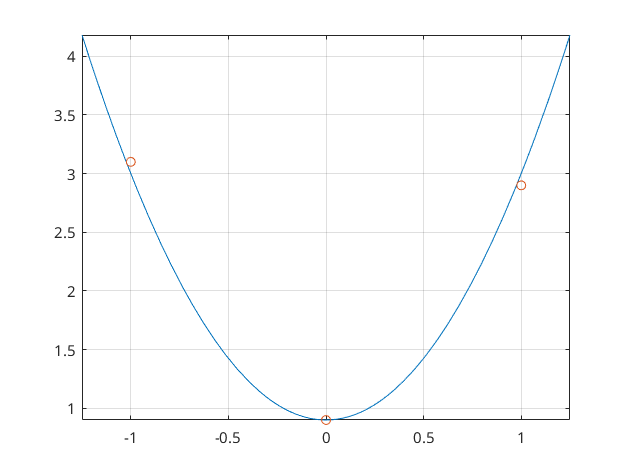

clf;
clear;
syms x;
y=2.1 * x^2 + 0.9;
fplot(y)
xlim([-1.25 1.25]);
hold on;
coeffs = [-1;0;1];
y = [3.1;0.9;2.9];
grid on;
plot(coeffs,y,"o");

## **Exercise 3 - 9.1.13**

**Q: **What straight line best fits the following data in the least squares sense?


$$\begin{array}{ll}
x \;\\ \hline
y\;
\end{array}
\left|
\begin{array}{cccc}
\;1 & 2 & 3 & 4\\\hline
\;0 & 1 & 1 & 2
\end{array}$$


**A: **We will find the normal equations, represent them in matrix form, and solve for our data set.

**Normal Equations:**


$$\left(\sum_{k=0}^mx_k^2\right)a+\left(\sum_{k=0}^mx_k\right)b=\sum_{k=0}^my_kx_k$$



$$\left(\sum_{k=0}^mx_k\right)a+(m+1)b=\sum_{k=0}^my_k$$


**Matrix Form:**


$$\left(\matrix{\sum x_k^2 & \sum x_k \cr\sum x_k & m+1}\right) \left(\matrix{a\cr b}\right)=\left(\matrix{\sum y_kx_k \cr \sum y_k}\right)$$



$$\sum x_k^2 = 30,\quad\sum x_k=10,\quad\sum y_kx_k=13 \quad \text{and}\quad \sum y_k=4$$


Now we solve:

clear all;
xi = 1:4;
yi = [0 1 1 2];

[~,n] = size(xi);

% A = [sum(xi^2) sum(xi); sum(xi) m+1] = [30 10; 10; 4]
A = [xi*xi' sum(xi); sum(xi) n];
% b = [sum(yi*xi); sum(yi)] = [13; 4]
b = [yi*xi'; sum(yi)];
coeffs = A\b

coeffs =     0.6000
   -0.5000



$$\therefore y=\frac{(6x-5)}{10}$$


## **Exercise 4 - 9.1.25**

**Q: **Find the normal equations for the following data points:


$$\begin{array}{ll}
x \;\\ \hline
y\;
\end{array}
\left|
\begin{array}{cccc}
\; 1.0 & 2.0 & 2.5 &3.0\\\hline
\; 3.7 & 4.1 & 4.3 & 5.0
\end{array}$$


Determine the straight line that best fits the data in the least squares sense. Plot the data points and the least squares line.

**A: **Normal equations:


$$\left(\sum_{k=0}^mx_k^2\right)a+\left(\sum_{k=0}^mx_k\right)b=\sum_{k=0}^my_kx_k$$



$$\left(\sum_{k=0}^mx_k\right)a+(m+1)b=\sum_{k=0}^my_k$$


Same as above, this time we have the following though:


$$\sum x_k^2 = 20.25,\quad\sum x_k=8.5,\quad\sum y_kx_k=37.65 \quad \text{and}\quad \sum y_k=17.1$$


clear;
clf;

xi = [1.0; 2.0; 2.5; 3.0];
yi = [3.7; 4.1; 4.3; 5.0];

[n,~] = size(xi);

A = [xi'*xi sum(xi); sum(xi) n];
b = [yi'*xi; sum(yi)];
coeffs = A\b

coeffs =     0.6000
    3.0000



$$\therefore y = 0.6x+3$$


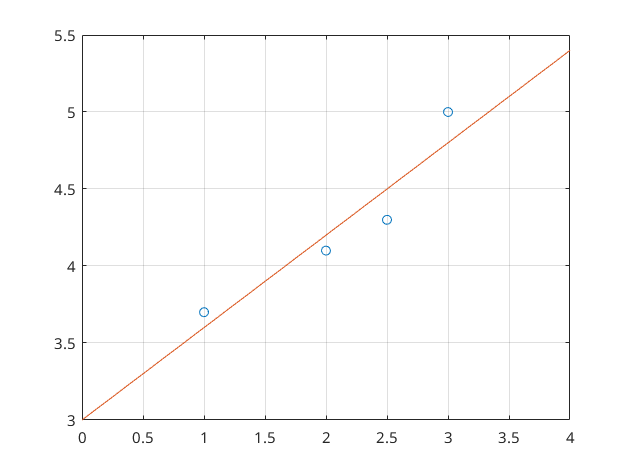


syms x;
plot(xi,yi,'o')
hold on;
fplot(0.6*x+3);
grid on;
xlim([0 4])